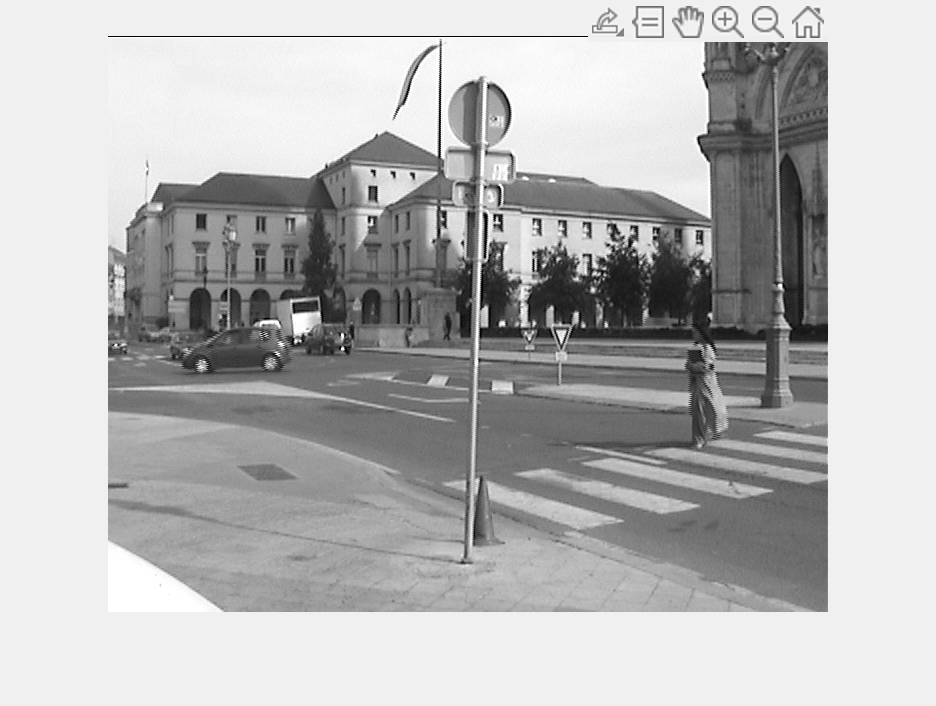

% Harris detector
% The code calculates
% the Harris Feature Points(FP) 
% 
% When u execute the code, the test image file opened
% and u have to select by the mouse the region where u
% want to find the Harris points, 
% then the code will print out and display the feature
% points in the selected region.
% You can select the number of FPs by changing the variables 
% max_N & min_N
% A. Ganoun

load Harris/Imag.mat

I =double(frame);
%****************************
imshow(frame);
k = waitforbuttonpress;
point1 = get(gca,'CurrentPoint');  %button down detected
rectregion = rbbox;  %%%return figure units

point2 = get(gca,'CurrentPoint');%%%%button up detected
point1 = point1(1,1:2); %%% extract col/row min and maxs
point2 = point2(1,1:2);
lowerleft = min(point1, point2);
upperright = max(point1, point2); 
ymin = round(lowerleft(1)); 
ymax = round(upperright(1));
xmin = round(lowerleft(2));
xmax = round(upperright(2));
%***********************************
Aj=6;
cmin=xmin-Aj; cmax=xmax+Aj; rmin=ymin-Aj; rmax=ymax+Aj;
min_N=12;max_N=16;
%%%%%%%%%%%%%%Intrest Points %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sigma=2; Thrshold=20; r=6; disp=1;
dx = [-1 0 1; -1 0 1; -1 0 1]; % The Mask 
    dy = dx';
    %%%%%% Compute x and y derivates
    Ix = conv2(I(cmin:cmax,rmin:rmax), dx, 'same');   
    Iy = conv2(I(cmin:cmax,rmin:rmax), dy, 'same');
    g = fspecial('gaussian',max(1,fix(6*sigma)), sigma); %%%%%% Gaussien Filter
    
    %%%%% computing products of derivatives
    Ix2 = conv2(Ix.^2, g, 'same');  
    Iy2 = conv2(Iy.^2, g, 'same');
    Ixy = conv2(Ix.*Iy, g,'same');
    %%%%%%%%%%%%%% Computing sums of products of derivatives
    k = 0.04;
    R11 = (Ix2.*Iy2 - Ixy.^2) - k*(Ix2 + Iy2).^2;
    R11=(1000/max(max(R11)))*R11;
    R=R11;
    ma=max(max(R));
    sze = 2*r+1; 
    MX = ordfilt2(R,sze^2,ones(sze));
    R11 = (R==MX)&(R>Thrshold); 
    count=sum(sum(R11(5:size(R11,1)-5,5:size(R11,2)-5)));
    
    
    loop=0;
    while (((count<min_N)|(count>max_N))&(loop<30))
        if count>max_N
            Thrshold=Thrshold*1.5;
        elseif count < min_N
            Thrshold=Thrshold*0.5;
        end
        
        R11 = (R==MX)&(R>Thrshold); 
        count=sum(sum(R11(5:size(R11,1)-5,5:size(R11,2)-5)));
        loop=loop+1;
    end
    
    
	R=R*0;
    R(5:size(R11,1)-5,5:size(R11,2)-5)=R11(5:size(R11,1)-5,5:size(R11,2)-5);
	[r1,c1] = find(R);
    PIP=[r1+cmin,c1+rmin]%% IP 

PIP =    504   422
   507   453
   498   458
   412   470
   495   471
   514   473
   428   477
   451   507
   486   515
   418   538


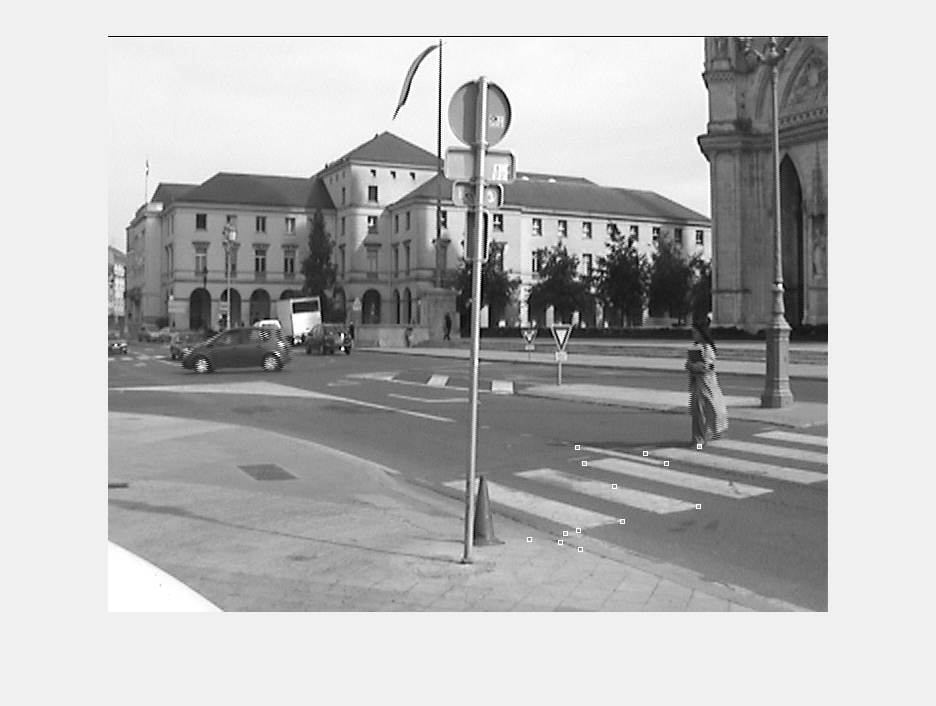

   

   %%%%%%%%%%%%%%%%%%%% Display
   
   Size_PI=size(PIP,1);
   for r=1: Size_PI
   I(PIP(r,1)-2:PIP(r,1)+2,PIP(r,2)-2)=255;
   I(PIP(r,1)-2:PIP(r,1)+2,PIP(r,2)+2)=255;
   I(PIP(r,1)-2,PIP(r,2)-2:PIP(r,2)+2)=255;
   I(PIP(r,1)+2,PIP(r,2)-2:PIP(r,2)+2)=255;
   
   end
   
   imshow(uint8(I))